# Correlate the base signal to the other signals and search for the peak

clc, clear, close all;

AddPaths()

Linux



base_sample_rate = 1000;
display_points = 1000;

First load all the data:

- Base .wav file

filename_base = 'pianosync.wav';
[y,Fs] = audioread(filename_base); % 8kHz sample 
base_sync_1k = SigConToBin(y(:, 1)', Fs, base_sample_rate);
base_sync_1k = double(base_sync_1k)-0.5;

- EMG data

filename_EMG = 'opensignals_000780589b3a_2023-12-19_11-12-23.txt';
emg_sample_rate = 1000;
data = readmatrix(filename_EMG, 'Range', 4, 'Delimiter', '\t');
emg_sync = data(:, 3);
emg_sync_1k = SigConToBin(emg_sync, emg_sample_rate,base_sample_rate);
emg_sync_1k = double(emg_sync_1k)-0.5;

- Blood data

raw_blood_data = load("perfusion_and_sync_19-Dec-2023-11_15_20.mat");
raw_blood_data_1k = raw_blood_data.fullDataSet(:, 1)';
blood_sample_rate = 1000;
raw_blood_data_1k = SigConToBin(raw_blood_data_1k, blood_sample_rate,base_sample_rate);
raw_blood_data_1k = double(raw_blood_data_1k)-0.5;

- Video capture data

AddPaths()

Linux


% Add path of 
% use this function example  
% 'data = BinToQTM(elina3.Trajectories.Unidentified.Data, [637.1 457.7 193.6], [10 10 10]);'

raw_video_data = load("elina3_nogapfilling.mat");
poi = [637.1 457.7 193.6];
tolerance_poi = [10 10 10];
video_sample_rate = 300;
video_capture_300 = double(QTMToBin(raw_video_data.elina3.Trajectories.Unidentified.Data, poi, tolerance_poi));

video_capture_1k = SigConToBin(video_capture_300, video_sample_rate, base_sample_rate);
video_capture_1k = double(video_capture_1k)-0.5;

Show all plots

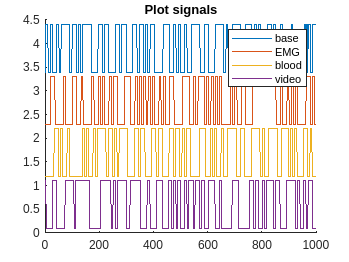

ShowSignals([ ...
    base_sync_1k(1:display_points);                 ...
    emg_sync_1k(1:display_points);                  ...
    raw_blood_data_1k(1:display_points);            ...
    video_capture_1k(1000:1000+display_points-1);   ...
])
title("Plot signals");

## Corolate the signals (using xcorr) to synchronise them

% Compute cross-correlation
[correlation_emg, lag_emg] = xcorr(base_sync_1k, emg_sync_1k);
correlation_emg = correlation_emg/max(correlation_emg); % normalize
correlation_emg = 20.*log10(correlation_emg); % to dB

[correlation_blood, lag_blood] = xcorr(base_sync_1k, raw_blood_data_1k);
correlation_blood = correlation_blood/max(correlation_blood); % normalize
correlation_blood = 20.*log10(correlation_blood); %to dB

[correlation_video, lag_video] = xcorr(base_sync_1k, video_capture_1k);
correlation_video = correlation_video/max(correlation_video); % normalize
correlation_video = 20.*log10(correlation_video); % to dB

% Plot cross-correlation
figure;

subplot(3,1,1);
plot(lag_emg, correlation_emg);

xlabel('Lag');          ylabel('Correlation in dB');
xlim([2000 6000]);      ylim([-40 1]);
title('Cross-correlation emg');

subplot(3,1,2);
plot(lag_blood, correlation_blood);

xlabel('Lag');          ylabel('Correlation in dB');
xlim([-5000 5000]);     ylim([-40 1]);
title('Cross-correlation blood');

subplot(3,1,3);
plot(lag_video, correlation_video);

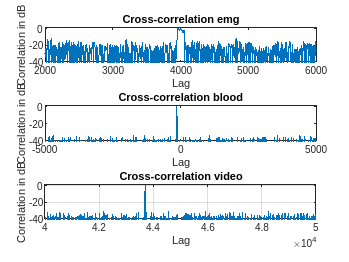

xlabel('Lag');          ylabel('Correlation in dB');
xlim([40000 50000]);    ylim([-40 1]);
title('Cross-correlation video');

grid on;

## Find EMG original sample freq

As seen in the plots both the blood and video data correlate to a single point (seen at the peaks), while the EMG data correlates to a range. This is because the EMG signal isn't sampled at 1kHz but has a small sampling error.

figure

subplot(1,2,1);
plot(lag_blood, correlation_blood);

title("Blood correlation")
xlim([-200, 200]);  ylim([-20, 1]);

subplot(1,2,2);
plot(lag_emg, correlation_emg);

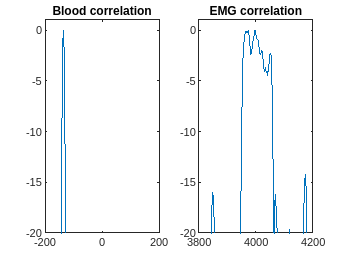

title("EMG correlation")
xlim([3800, 4200]); ylim([-20, 1]);

Let's compare the EMG correlation to the blood correlation. ***!!!!!!!!!!!!!!!! --> conclusie trekken***

# Align the signals with the base wave

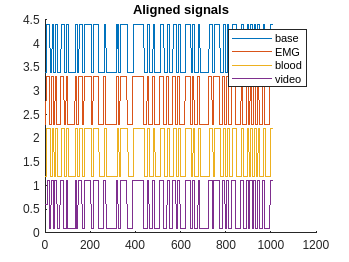

[base_sync_1k, emg_sync_1k, lag_emg_1] = Align(base_sync_1k, emg_sync_1k);
[base_sync_1k, raw_blood_data_1k, lag_blood_1] = Align(base_sync_1k, raw_blood_data_1k);
[base_sync_1k, video_capture_1k, lag_video_1] = Align(base_sync_1k, video_capture_1k);

full_lag =  min([lag_emg_1 lag_blood_1 lag_video_1]);
full_lag = 1*(full_lag == 0)+full_lag*(full_lag ~= 0);

ShowSignals([ ...
    base_sync_1k(abs(full_lag)-10:abs(full_lag)+display_points);        ...
    emg_sync_1k(abs(full_lag)-10:abs(full_lag)+display_points);         ...
    raw_blood_data_1k(abs(full_lag)-10:abs(full_lag)+display_points);   ...
    video_capture_1k(abs(full_lag)-10:abs(full_lag)+display_points);    ...
])
title("Aligned signals");

## Cut the synced signals to the same size

% Now cut off all the signals so we have a synced signal. 
% Find the lowest range.
ranges = [length(base_sync_1k) length(emg_sync_1k), length(raw_blood_data_1k), length(video_capture_1k)];
minimum  = min(ranges);
base_sync_1k = base_sync_1k(abs(full_lag):minimum);
emg_sync_1k = emg_sync_1k(abs(full_lag):minimum);
raw_blood_data_1k = raw_blood_data_1k(abs(full_lag):minimum);
video_capture_1k = video_capture_1k(abs(full_lag):minimum);


## Correlate the start and end of the signal

As seen in the image, the correlation of the blood data is similar for both the beginning and end of the data samples while there is a shift between the start and end of the EMG data.

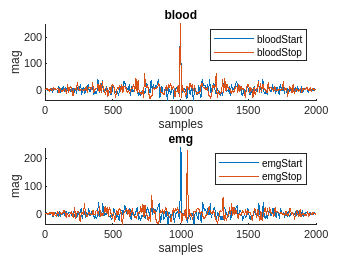

frame_size = 1000;

% Correlate start:  First 1000 samples of the signals
[emg_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k(1:frame_size));
[blood_corr_start, ~] = xcorr(base_sync_1k(1:frame_size), raw_blood_data_1k(1:frame_size));

% Correlate end:    Last 1000 samples of the signals
[emg_corr_end, ~] = xcorr(base_sync_1k(end - frame_size:end), emg_sync_1k(end - frame_size:end));
[blood_corr_end, ~] = xcorr(base_sync_1k(end - frame_size:end), raw_blood_data_1k(end - frame_size:end));

subplot(2,1,1);
title("blood")
hold on;
plot(blood_corr_start, "DisplayName","bloodStart")
plot(blood_corr_end, "DisplayName","bloodStop")
hold off;
xlabel("samples"); ylabel("mag");
xlim([0, 2000]);
legend()

subplot(2,1,2);
title("emg")
hold on;
plot(emg_corr_start, "DisplayName","emgStart")
plot(emg_corr_end, "DisplayName","emgStop")
hold off;
xlabel("samples"); ylabel("mag");
xlim([0, 2000]);
legend()

The samples at wich the 2 peaks can be located by looking for the largest magnitude value. By subtracting them from each other, we get the total shift in samples over the synchronised signal.

[~, max_start] = max(emg_corr_start);
[~, max_end] = max(emg_corr_end);
total_shift = max_end - max_start;


By dividing the total shift with the length of the signal, we get an estimation of what the shift in sampling frequency is.

shift_error = total_shift / length(base_sync_1k)

shift_error =       0.000615941079338453


## Resample emg with accuired shift error

- Re-read the EMG data and sample it using the new sampling rate.

filename_EMG = 'opensignals_000780589b3a_2023-12-19_11-12-23.txt';
data = readmatrix(filename_EMG, 'Range', 4, 'Delimiter', '\t');

format longG
emg_sample_rate_low = 1000 - shift_error

emg_sample_rate_low =           999.999384058921


emg_sample_rate_high = 1000 + shift_error

emg_sample_rate_high =           1000.00061594108



emg_sync = data(:, 3);
emg_sync_1k_low = SigConToBin(emg_sync,emg_sample_rate_low,base_sample_rate);
emg_sync_1k_low = double(emg_sync_1k_low)-0.5;

emg_sync = data(:, 3);
emg_sync_1k_high = SigConToBin(emg_sync,emg_sample_rate_high,base_sample_rate);
emg_sync_1k_high = double(emg_sync_1k_high)-0.5;

- View the new correlation

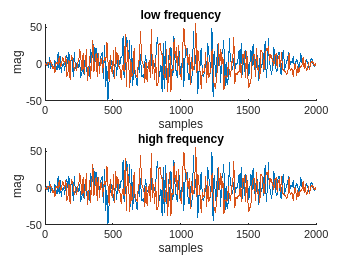

frame_size = 1000;

% Correlate start:  First 1000 samples of the signals
[emg_corr_low_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k_low(1:frame_size));
[emg_corr_high_start, ~] = xcorr(base_sync_1k(1:frame_size), emg_sync_1k_high(1:frame_size));

% Correlate end:    Last 1000 samples of the signals
[emg_corr_low_end, ~] = xcorr(base_sync_1k(end - frame_size:end), emg_sync_1k_low(end - frame_size:end));
[emg_corr_high_end, ~] = xcorr(base_sync_1k(end - frame_size:end), emg_sync_1k_high(end - frame_size:end));

figure
subplot(2,1,1);
title("low frequency")
hold on;
plot(emg_corr_low_start, "DisplayName","low frequency start")
plot(emg_corr_low_end, "DisplayName","low frequency stop")
hold off;
xlabel("samples"); ylabel("mag");
xlim([0, 2000]);
%legend()

subplot(2,1,2);
title("high frequency")
hold on;
plot(emg_corr_high_start, "DisplayName","high frequency start")
plot(emg_corr_high_end, "DisplayName","high frequency stop")
hold off;
xlabel("samples"); ylabel("mag");
xlim([0, 2000]);

%legend()

- Re-sync the EMG data to the base signal

[base_sync_1k, emg_sync_1k, lag_emg_1] = Align(base_sync_1k, emg_sync_1k_low);

full_lag = min([lag_emg_1 lag_blood_1 lag_video_1]);
full_lag = 1*(full_lag == 0)+full_lag*(full_lag ~= 0);

- Plot the data

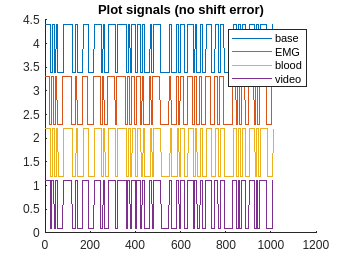

ShowSignals([ ...
    base_sync_1k(abs(full_lag)-10:abs(full_lag)+display_points);        ...
    emg_sync_1k(abs(full_lag)-10:abs(full_lag)+display_points);         ...
    raw_blood_data_1k(abs(full_lag)-10:abs(full_lag)+display_points);   ...
    video_capture_1k(abs(full_lag)-10:abs(full_lag)+display_points);    ...
])
title("Plot signals (no shift error)");